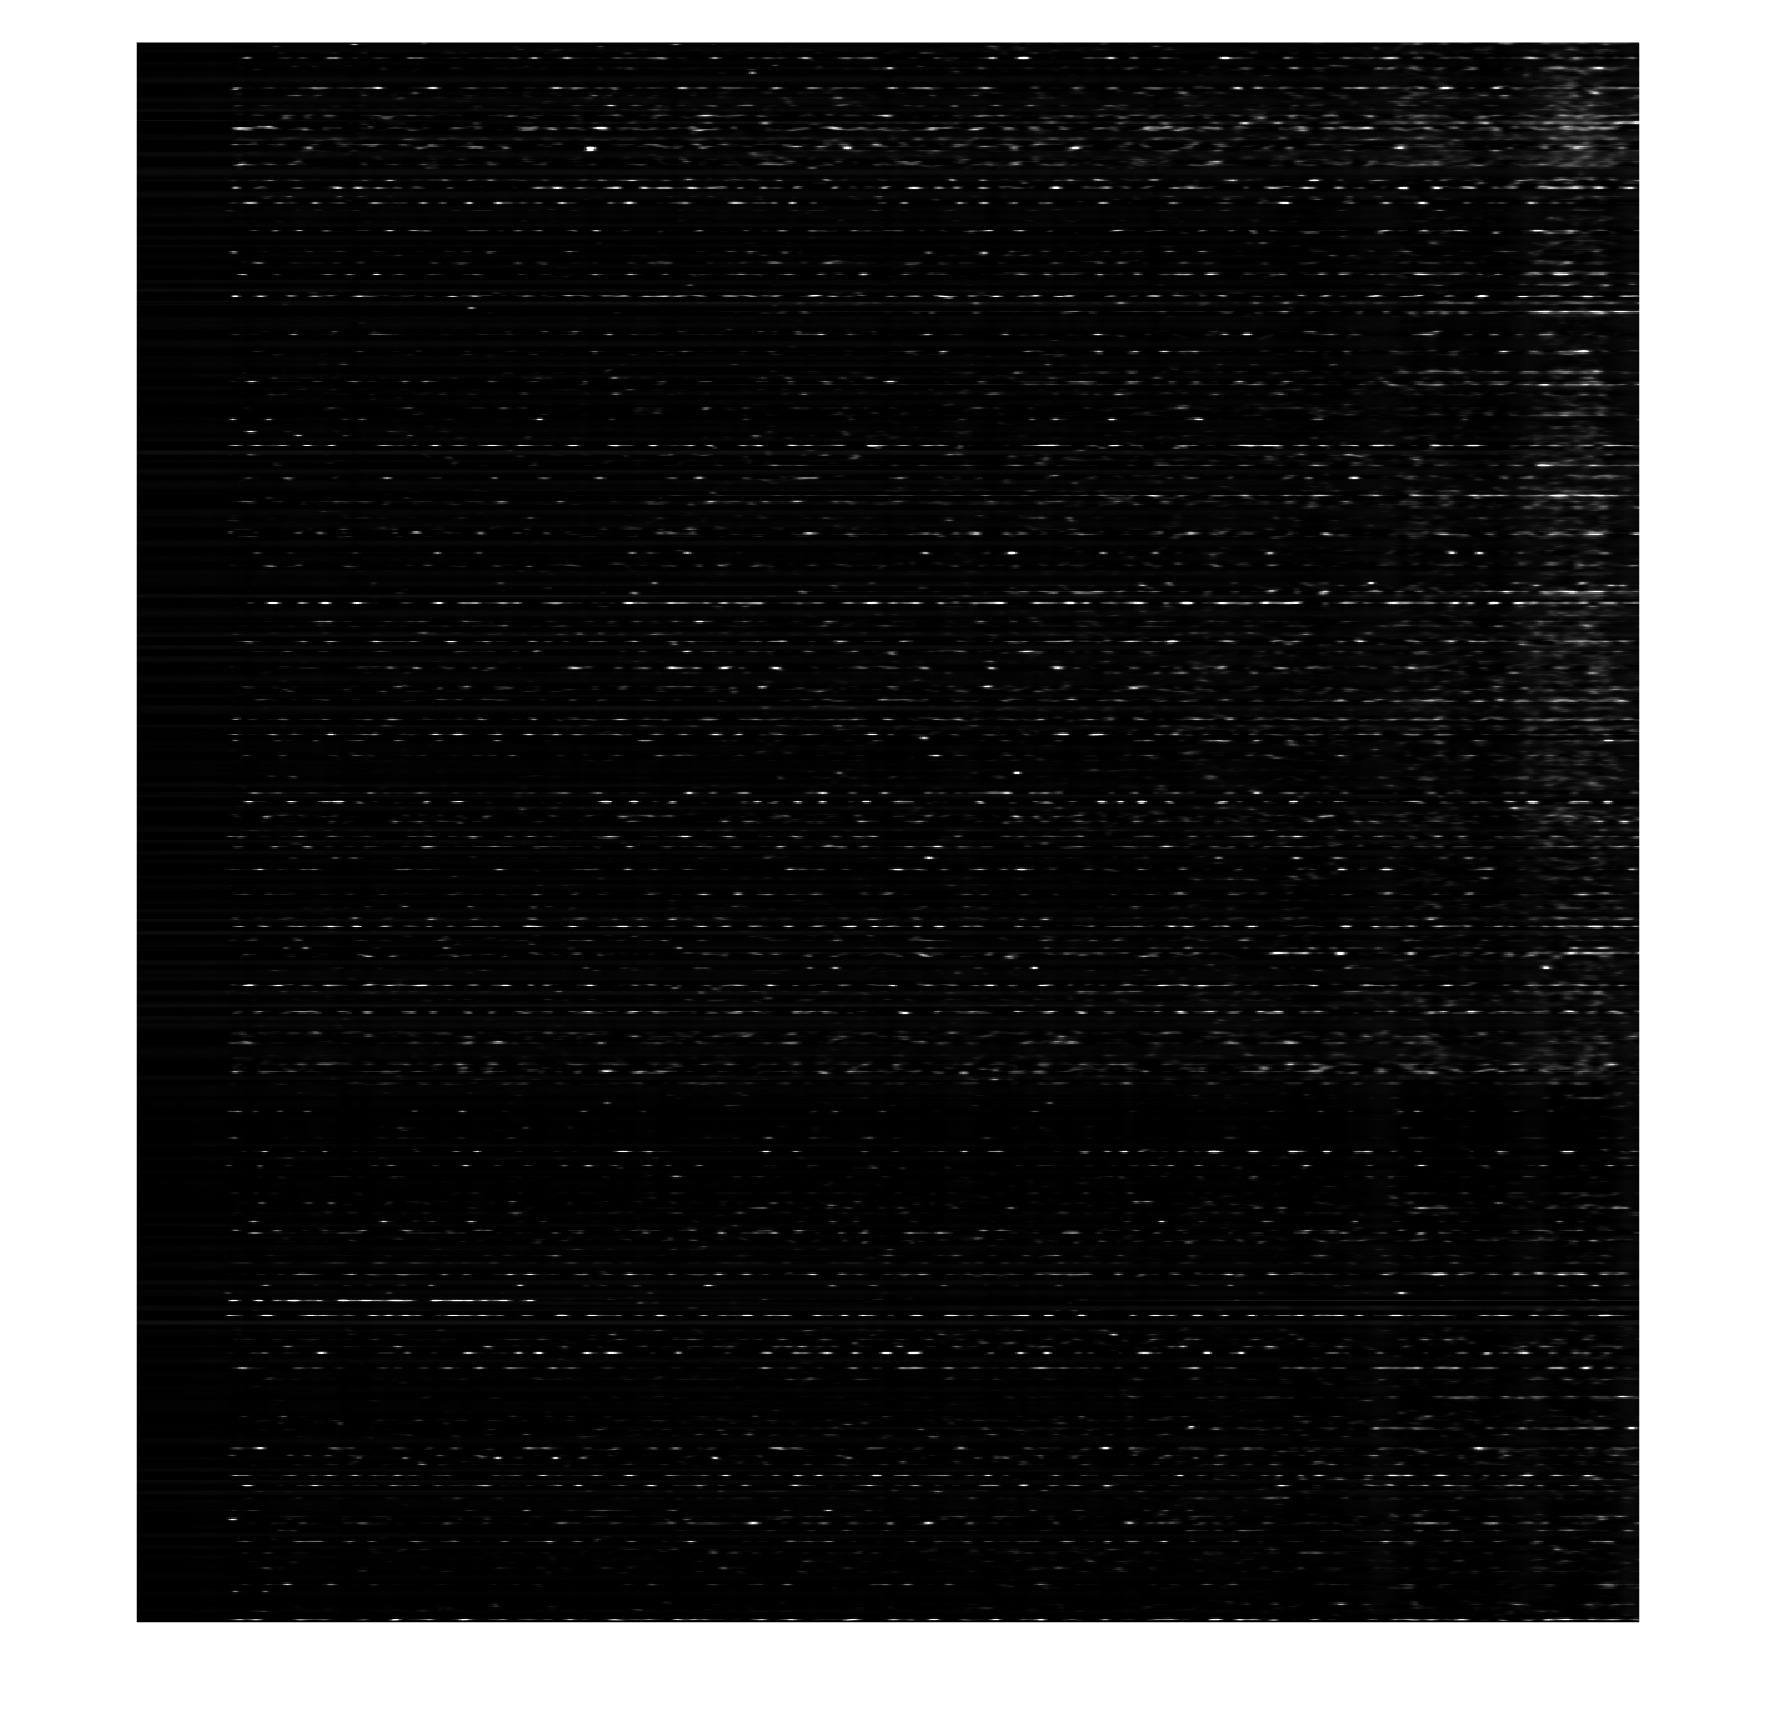

figure;
% img = imread("C:\Users\kmoradi\Downloads\test.png");
% bl = load_lz4("V:\tif\AD4_ds_4.5x_ABeta_z1200\cache_deconvolution_Ex_642_Em_690\bl_37.lz4");
load("V:\tif\AD4_ds_4.5x_ABeta_z1200\cache_deconvolution_Ex_642_Em_690\min_max.mat");
amplification = 1;
scal = 2^16 - 1;
ul = 512;
R = squeeze(bl(:, floor(size(bl, 2)/2), :));
R = R .* (scal .* amplification ./ deconvmax);
R = R - amplification;
R = round(R);
R = min(R, scal);
R = max(R, 0);
R = uint16(R);
img = R;
imshow(img, [0, ul]);

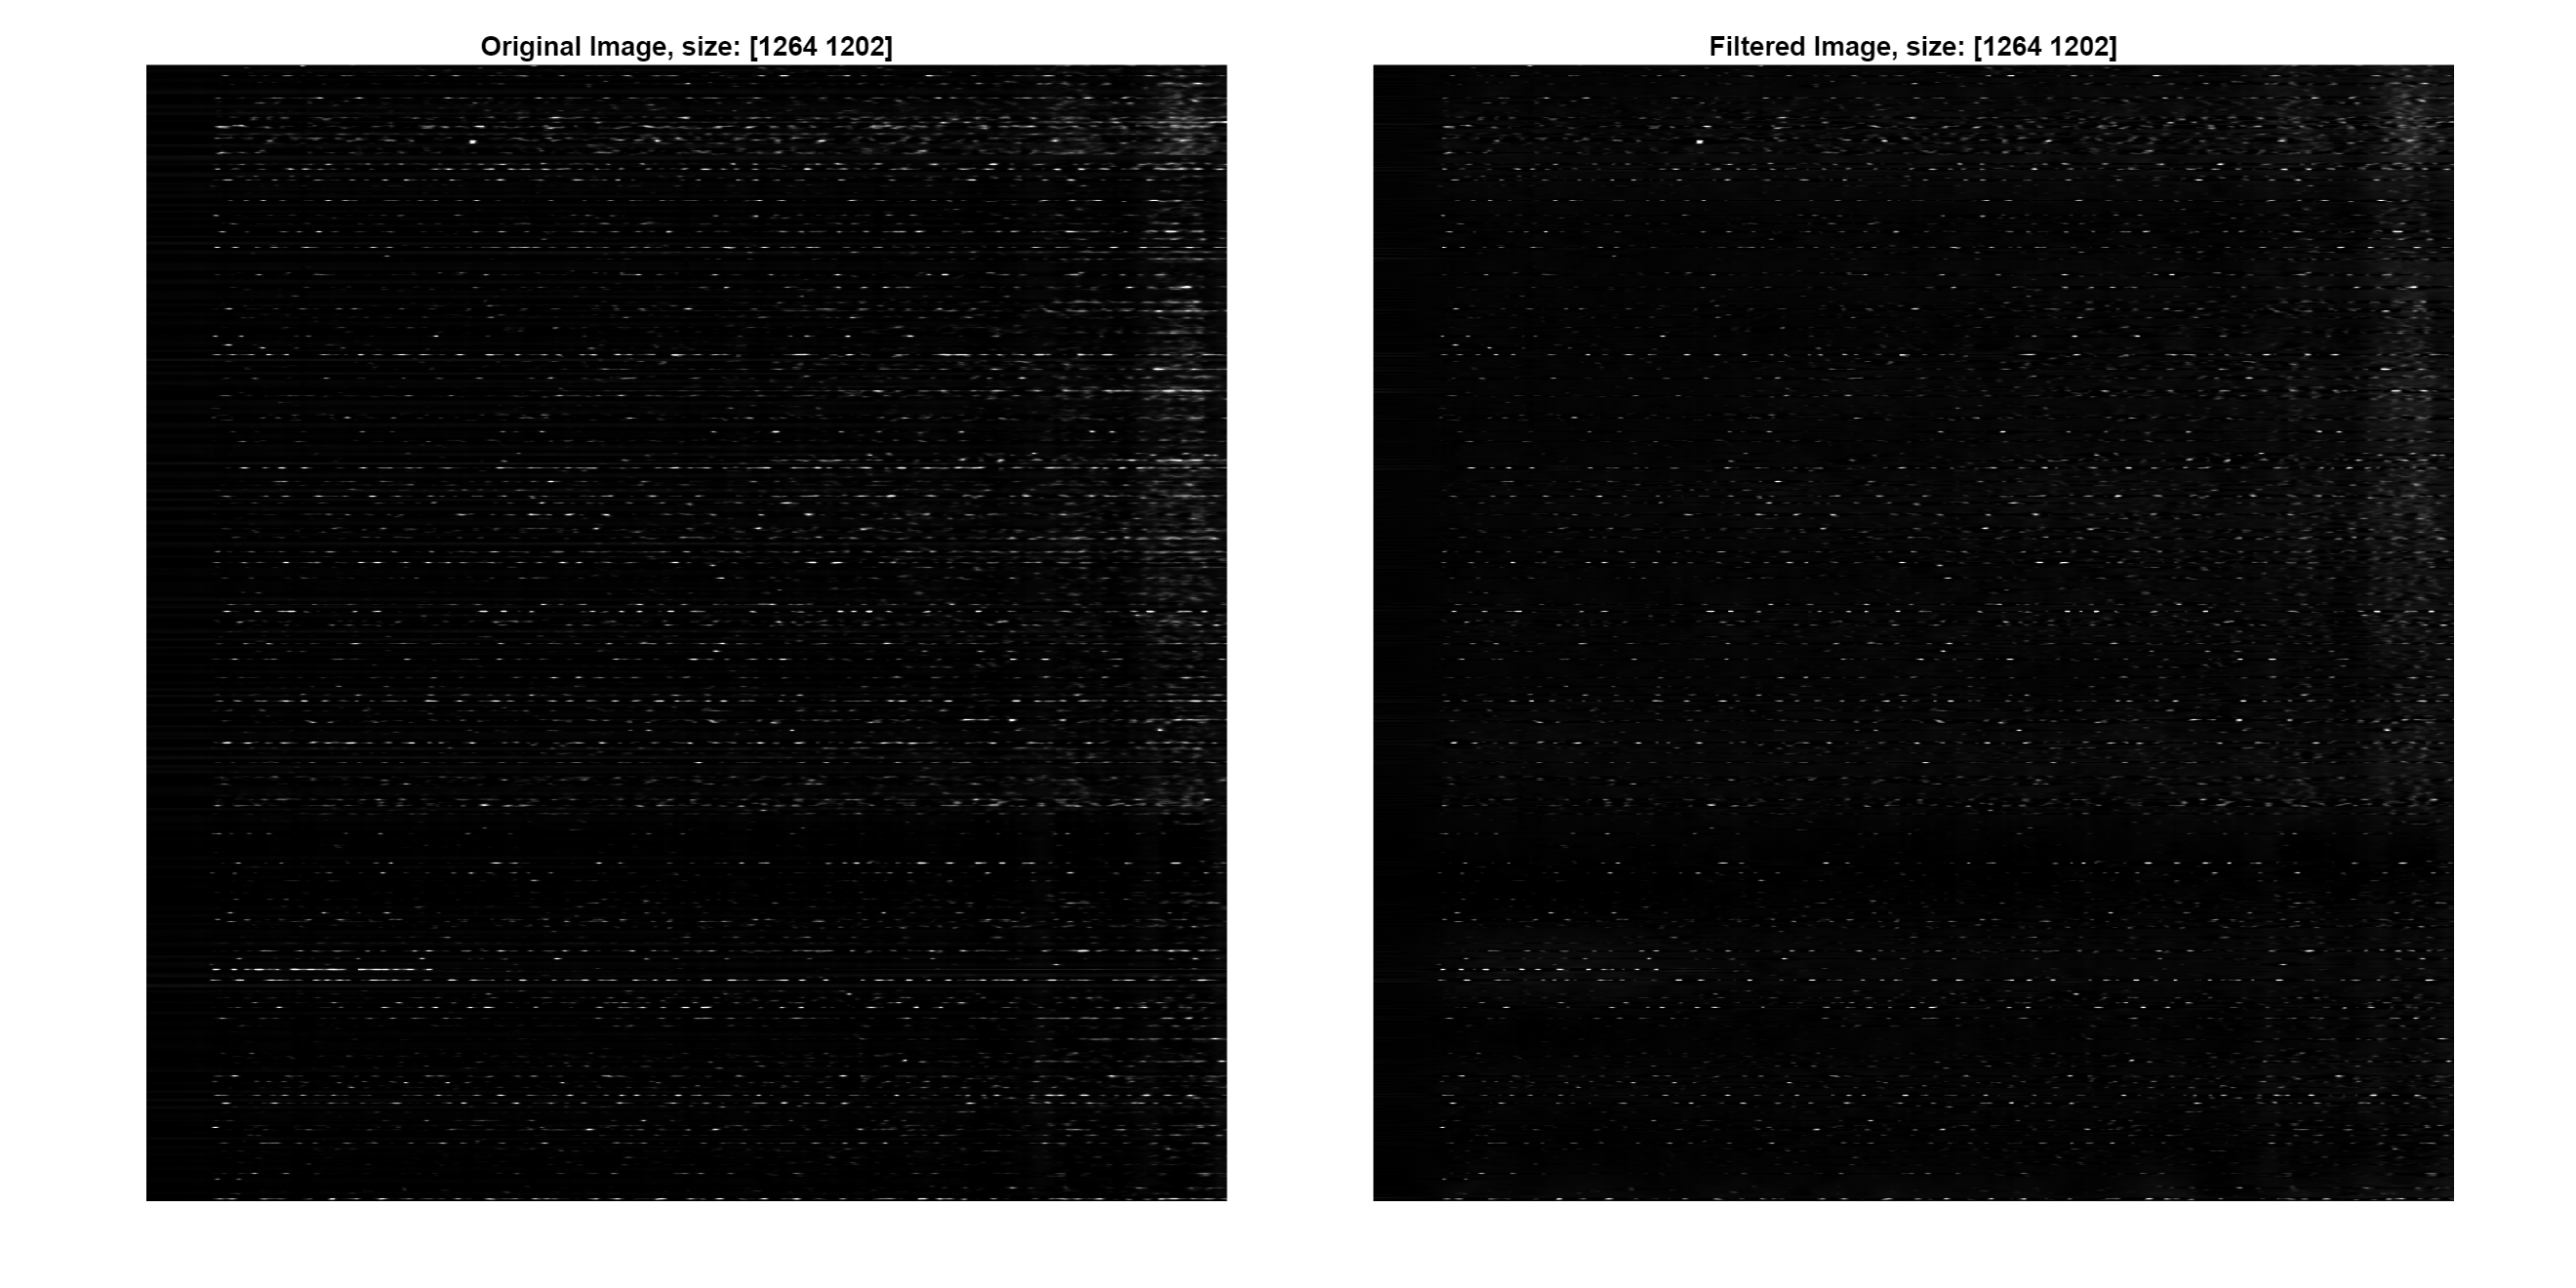

% Apply filtering
img_filtered = filter_subband(img, 2000, 0, "db9", [2]);

% Create larger figure window
figure('Position', [100, 100, 1800, 900]);  % [left, bottom, width, height]

% Use tiled layout for consistent sizing
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

% Original image (XZ slice at middle Y)
nexttile;
imshow(img, [0 ul]);
title("Original Image, size: " + mat2str(size(img)));
axis image;

% Filtered image (XZ slice at middle Y)
nexttile;
imshow(img_filtered, [0 ul]);
title("Filtered Image, size: " + mat2str(size(img_filtered)));
axis image;

lsqr = (img_filtered - img).^2;
sum(lsqr(:))

ans = 94026795

function img = filter_subband(img, sigma, levels, wavelet, axes)
    % Applies Gaussian notch filtering to wavelet subbands
    % axes: [1] for vertical filtering, [2] for horizontal filtering

    original_class = class(img);
    img = im2single(img);
    original_size = size(img);

    % Pad image to even dimensions
    pad_x = mod(original_size(1), 2);
    pad_y = mod(original_size(2), 2);
    img = padarray(img, [pad_x, pad_y], 'post');

    % Dynamic range compression
    img = log1p(img);

    % Wavelet decomposition
    if levels == 0
        levels = wmaxlev(size(img), wavelet);
    end
    [C, S] = wavedec2(img, levels, wavelet);

    % Track starting index in C (skip approximation part)
    start_idx = prod(S(1, :));
    for n = 1:levels
        sz = prod(S(n + 1, :));

        % Indices for detail coefficients at level n
        idxH = start_idx + (1:sz);
        idxV = idxH(end) + (1:sz);
        idxD = idxV(end) + (1:sz);

        % Apply filtering
        % if ismember(3, axes)
        %     % Diagonal filtering on D
        %     D = reshape(C(idxD), S(n + 1, :));
        %     D = filter_coefficient(D, sigma / mean(size(D)), 3);
        %     C(idxD) = D(:);
        % end
        if ismember(2, axes)
            % Horizontal filtering on H
            H = reshape(C(idxH), S(n + 1, :));
            H = filter_coefficient(H, sigma / size(H, 2), 2);
            C(idxH) = H(:);
        end
        if ismember(1, axes)
            % Vertical filtering on V
            V = reshape(C(idxV), S(n + 1, :));
            V = filter_coefficient(V, sigma / size(V, 1), 1);
            C(idxV) = V(:);
        end  
        start_idx = idxD(end);  % Move to next level
    end

    % Wavelet reconstruction
    img = waverec2(C, S, wavelet);
    img = expm1(img);

    % Crop
    img = img(1:end - pad_x, 1:end - pad_y);

    % Restore class
    switch original_class
        case 'uint8'
            img = im2uint8(img);
        case 'uint16'
            img = im2uint16(img);
        case 'double'
            img = im2double(img);
        otherwise
            img = max(min(img, 1), 0);
    end
end

function mat = filter_coefficient(mat, sigma, axis)
    % clamping sigma to avoid potential division by zero or numerical instability
    sigma = max(sigma, 1e-5);
    n = size(mat, axis);
    mat = fft(mat, n, axis);

    % Gaussian filter
    g = gaussian_notch_filter_1d(n, sigma);
    if axis == 1
        g = repmat(g(:), 1, size(mat, 2));
    elseif axis == 2
        g = repmat(g, size(mat, 1), 1);
    else
        error('Invalid axis');
    end

    % Apply filter to complex spectrum
    mat = mat .* complex(g, g);
    mat = real(ifft(mat, n, axis));
end

function g = gaussian_notch_filter_1d(n, sigma)
    x = (0:n-1) - floor(n/2);
    g = 1 - exp(-(x .^ 2) / (2 * sigma ^ 2));
    g = fftshift(g);
end
